#### Boas práticas

clear all;
close all;
clc;

### Leitura do arquivo.wav

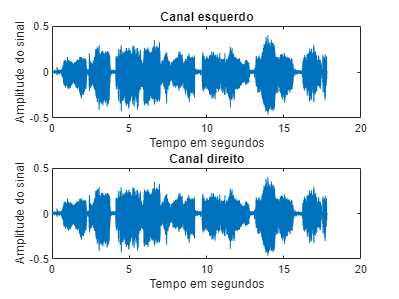

% audioread Read audio files
%    [Y, FS] = audioread(FILENAME) reads an audio file specified by the
%   character vector or string scalar FILENAME, returning the sampled data
%  in Y and the sample rate FS, in Hertz.

[Y,FS] = audioread("Audio1860.wav");

% Criando a variavel tempo

TS = 1/FS;                      % Tempo entre amostras
Npontos = length(Y);            % Numero de pontos do vetor Y
Vfinal = (Npontos - 1)*TS;      % valor final

tempo = linspace(0,Vfinal,Npontos);

figure(1);

subplot(2,1,1);
plot(tempo,Y(:,1));
xlabel("Tempo em segundos");
ylabel("Amplitude do sinal");
title("Canal esquerdo");

subplot(2,1,2);
plot(tempo,Y(:,2));
xlabel("Tempo em segundos");
ylabel("Amplitude do sinal");
title("Canal direito");

### Ouvir um arquivo.wav

% audiowrite(FILENAME,Y,FS)  writes data Y to an audio
%     file specified by the file name FILENAME, with a sample rate
%     of FS Hz.
%     Stereo data should be specified as a matrix with two columns.
%     Multi-channel data should be specified as a matrix of N columns.

% sound(Y,FS) sends the signal in vector Y (with sample frequency
%     FS) out to the speaker on platforms that support sound. Values in
%     Y are assumed to be in the range -1.0 <= y <= 1.0. Values outside
%     that range are clipped.  Stereo sounds are played, on platforms
%     that support it, when Y is an N-by-2 matrix.

%% sound(Y,FS);
 

### Aplicar a FFT - Fast Fourrier Transform

% Discrete Fourier transform.
%     fft(X) is the discrete Fourier transform (DFT) of vector X.  For
%     matrices, the fft operation is applied to each column. For N-D
%     arrays, the fft operation operates on the first non-singleton
%     dimension.

FY = fftshift(fft(Y));


### Visualizar a FFT e interpretar

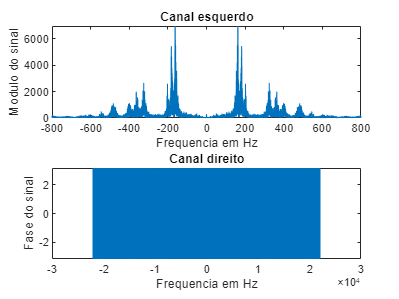

% Criar a variavel frequencia

frequencia = linspace(-FS/2,FS/2,Npontos);

figure(2);

subplot(2,1,1);
plot(frequencia,abs(FY(:,1)));
xlabel("Frequencia em Hz");
ylabel("Modulo do sinal");
title("Canal esquerdo");

subplot(2,1,2);
plot(frequencia,angle(FY(:,2)));
xlabel("Frequencia em Hz");
ylabel("Fase do sinal");
title("Canal direito");

subplot(2,1,1)
xlim([-2135 1912])
ylim([0 7553])

subplot(2,1,1)
xlim([-800 800])
ylim([0 6950])

### Conclusão

Pode-se concluir que essa faixa 1860 está contida em aproximadamente 600 Hz dos 41000 Hz em que esse arquivo possui.